# Expand Example 2.16:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider again the first-order RC circuit used in Example 2.8 and shown in the figure below:

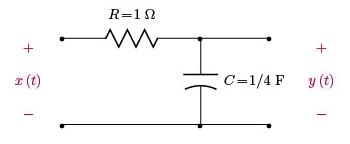

The initial value of the output at $t=0$ is $y(0)=y_{0}$.  Let the input signal be

        
$$x(t)=A\,\cos(\omega t)$$


The homogeneous solution is in the form

        $y_{h}(t)=c\,e^{4t}$  for $t>=0$.

The particular solution is in the form

        
$$y_{p}(t)=k_{1}\,\cos(\omega t)+k_{2}\,\sin(\omega t)$$


Experiment by changing $y_{0}$, $A$ and $\omega$.

y0  = 2; % Initial capacitor voltage
A   = 20; % Amplitude
omg = 8; % Radian frequency (rad/s)

Following eqns must be satisfied:

        $4k_{1}+\omega k_{2}-A=0$                    (2.102)

        $4k_{2}-\omega k_{1}=0$                           (2.103)

        
$$y_{0}=c+k_{1}$$


Determine and graph the forced response $y(t)$.

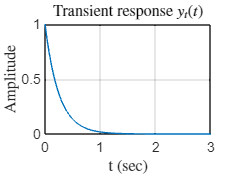

matA = [4,omg;-omg,4];  
vecB = [A;0];
K = matA\vecB;     % Solve eqns for k1 and k2
c = y0 - K(1);
t = [0:0.01:3];    % Vector of time instants
yt = c*exp(-4*t);  % Transient response
yss = K(1)*cos(omg*t)+K(2)*sin(omg*t);  % Steady-state response
y = yt+yss;        % Forced response
plot(t,yt); grid;
set(0,'defaultTextInterpreter','latex')
title('Transient response $y_{t}(t)$');
xlabel('t (sec)'); 
ylabel('Amplitude');

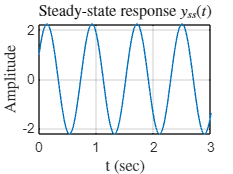

plot(t,yss); grid;
title('Steady-state response $y_{ss}(t)$');
xlabel('t (sec)'); 
ylabel('Amplitude');

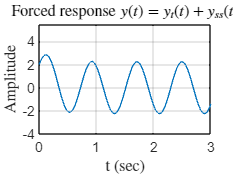

plot(t,y); grid;
axis([0,3,-4,5.5]);
title('Forced response $y(t)=y_t(t)+y_{ss}(t)$');
xlabel('t (sec)'); 
ylabel('Amplitude');

set(0,'defaultTextInterpreter','tex')